## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6S_Drive = [50 35 20 35]*NS_L6/1e3 * StimulusFac;
L6C_Drive = [50 35 20 35]*NC_L6/1e3 * StimulusFac;
L6I_Drive = [50 35 20 35]*NI_L6/1e3 * StimulusFac;

rE_L6_Drive = [L6S_Drive(OD_S),L6C_Drive(OD_C)]';
rI_L6_Drive = L6I_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
          'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 10.6239

FrECNow = 58.9901

FrINow = 80.7700

Elapsed time is 2.665627 seconds.


SampleInd = 3

FrESNow = 7.2461

FrECNow = 68.7160

FrINow = 86.7430

Elapsed time is 4.716574 seconds.


SampleInd = 4

FrESNow = 7.0639

FrECNow = 18.7531

FrINow = 53.0258

Elapsed time is 6.872338 seconds.


SampleInd = 5

FrESNow = 9.6845

FrECNow = 93.6938

FrINow = 106.0377

Elapsed time is 9.186142 seconds.


SampleInd = 6

FrESNow = 5.7503

FrECNow = 35.6198

FrINow = 64.9971

Elapsed time is 11.517857 seconds.


SampleInd = 7

FrESNow = 8.1646

FrECNow = 38.6914

FrINow = 68.0911

Elapsed time is 13.170603 seconds.


SampleInd = 8

FrESNow = 7.9561

FrECNow = 97.0272

FrINow = 108.2854

Elapsed time is 16.258745 seconds.


SampleInd = 9

FrESNow = 5.6724

FrECNow = 11.2938

FrINow = 48.3223

Elapsed time is 17.494582 seconds.


SampleInd = 10

FrESNow = 9.5594

FrECNow = 84.7037

FrINow = 100.4185

Elapsed time is 20.451632 seconds.


SampleInd = 11

FrESNow = 5.9929

FrECNow = 54.2840

FrINow = 78.5894

Elapsed time is 22.286816 seconds.


SampleInd = 12

FrESNow = 7.1133

FrECNow = 26.3556

FrINow = 59.0242

Elapsed time is 24.459566 seconds.


SampleInd = 13

FrESNow = 8.6266

FrECNow = 97.5506

FrINow = 108.5605

Elapsed time is 26.762720 seconds.


SampleInd = 14

FrESNow = 5.7218

FrECNow = 15.3062

FrINow = 51.0672

Elapsed time is 28.825303 seconds.


SampleInd = 15

FrESNow = 9.1830

FrECNow = 76.0148

FrINow = 94.5867

Elapsed time is 30.994012 seconds.


SampleInd = 16

FrESNow = 6.3374

FrECNow = 60.0420

FrINow = 81.8892

Elapsed time is 33.581311 seconds.


SampleInd = 17

FrESNow = 6.9432

FrECNow = 23.0790

FrINow = 56.4273

Elapsed time is 35.033378 seconds.


SampleInd = 18

FrESNow = 8.8768

FrECNow = 91.6617

FrINow = 104.9208

Elapsed time is 38.053546 seconds.


SampleInd = 19

FrESNow = 6.0335

FrECNow = 23.9210

FrINow = 56.9153

Elapsed time is 39.428924 seconds.


SampleInd = 20

FrESNow = 8.8154

FrECNow = 52.5605

FrINow = 77.8102

Elapsed time is 41.932931 seconds.


SampleInd = 21

FrESNow = 7.3460

FrECNow = 78.8914

FrINow = 95.1254

Elapsed time is 44.061834 seconds.


Elapsed time is 44.062626 seconds.


SampleInd = 22

FrESNow = 6.4582

FrECNow = 16.4148

FrINow = 51.9551

Elapsed time is 1.935913 seconds.


SampleInd = 23

FrESNow = 8.9449

FrECNow = 86.8716

FrINow = 101.4221

Elapsed time is 4.159579 seconds.


SampleInd = 24

FrESNow = 6.1202

FrECNow = 33.5630

FrINow = 63.7091

Elapsed time is 6.396791 seconds.


SampleInd = 25

FrESNow = 8.3643

FrECNow = 42.5580

FrINow = 70.9978

Elapsed time is 8.074197 seconds.


SampleInd = 26

FrESNow = 8.3029

FrECNow = 79.1531

FrINow = 96.4643

Elapsed time is 10.921129 seconds.


SampleInd = 27

FrESNow = 6.2036

FrECNow = 19.3630

FrINow = 53.5068

Elapsed time is 12.302921 seconds.


SampleInd = 28

FrESNow = 9.3191

FrECNow = 84.5136

FrINow = 100.6220

Elapsed time is 15.204996 seconds.


SampleInd = 29

FrESNow = 5.9040

FrECNow = 37.3481

FrINow = 66.6597

Elapsed time is 16.786635 seconds.


SampleInd = 30

FrESNow = 8.2502

FrECNow = 37.7556

FrINow = 67.3604

Elapsed time is 19.127298 seconds.


SampleInd = 31

FrESNow = 8.4510

FrECNow = 98.4568

FrINow = 109.4647

Elapsed time is 21.446728 seconds.


SampleInd = 32

FrESNow = 5.4354

FrECNow = 18.7407

FrINow = 53.5160

Elapsed time is 23.500056 seconds.


SampleInd = 33

FrESNow = 8.8845

FrECNow = 61.8296

FrINow = 84.3427

Elapsed time is 25.413450 seconds.


SampleInd = 34

FrESNow = 6.8093

FrECNow = 71.4420

FrINow = 89.8855

Elapsed time is 28.105634 seconds.


SampleInd = 35

FrESNow = 6.6798

FrECNow = 18.8568

FrINow = 53.5530

Elapsed time is 29.519820 seconds.


SampleInd = 36

FrESNow = 9.0206

FrECNow = 92.4790

FrINow = 105.4596

Elapsed time is 32.479512 seconds.


SampleInd = 37

FrESNow = 5.8886

FrECNow = 29.3728

FrINow = 60.9203

Elapsed time is 33.884076 seconds.


SampleInd = 38

FrESNow = 8.4708

FrECNow = 48.5210

FrINow = 75.3428

Elapsed time is 36.319906 seconds.


SampleInd = 39

FrESNow = 7.5292

FrECNow = 87.5506

FrINow = 101.1608

Elapsed time is 38.529408 seconds.


SampleInd = 40

FrESNow = 6.0159

FrECNow = 15.0494

FrINow = 50.9978

Elapsed time is 40.567745 seconds.


SampleInd = 41

FrESNow = 9.2554

FrECNow = 86.8519

FrINow = 101.2926

Elapsed time is 42.798409 seconds.


Elapsed time is 42.799164 seconds.


SampleInd = 42

FrESNow = 6.0357

FrECNow = 35.2321

FrINow = 65.1567

Elapsed time is 2.179482 seconds.


SampleInd = 43

FrESNow = 8.2173

FrECNow = 40.6099

FrINow = 69.1733

Elapsed time is 3.783376 seconds.


SampleInd = 44

FrESNow = 8.2030

FrECNow = 97.9753

FrINow = 108.6345

Elapsed time is 6.829267 seconds.


SampleInd = 45

FrESNow = 5.3344

FrECNow = 12.5012

FrINow = 48.6993

Elapsed time is 8.086694 seconds.


SampleInd = 46

FrESNow = 9.2247

FrECNow = 78.3531

FrINow = 96.1152

Elapsed time is 10.936169 seconds.


SampleInd = 47

FrESNow = 6.1915

FrECNow = 42.1877

FrINow = 69.2982

Elapsed time is 12.530733 seconds.


SampleInd = 48

FrESNow = 8.1218

FrECNow = 38.3802

FrINow = 67.8182

Elapsed time is 14.834609 seconds.


SampleInd = 49

FrESNow = 8.2765

FrECNow = 85.8568

FrINow = 100.0948

Elapsed time is 16.977157 seconds.


SampleInd = 50

FrESNow = 6.4966

FrECNow = 18.9877

FrINow = 54.2953

Elapsed time is 19.047495 seconds.


SampleInd = 51

FrESNow = 9.1665

FrECNow = 83.5951

FrINow = 100.1942

Elapsed time is 21.253499 seconds.


SampleInd = 52

FrESNow = 5.9632

FrECNow = 37.3037

FrINow = 65.9891

Elapsed time is 23.501082 seconds.


SampleInd = 53

FrESNow = 8.3863

FrECNow = 46.2617

FrINow = 73.6571

Elapsed time is 25.204448 seconds.


SampleInd = 54

FrESNow = 7.6115

FrECNow = 88.0864

FrINow = 101.6487

Elapsed time is 28.141888 seconds.


SampleInd = 55

FrESNow = 5.9841

FrECNow = 13.3753

FrINow = 49.5942

Elapsed time is 29.452100 seconds.


SampleInd = 56

FrESNow = 9.3992

FrECNow = 85.3160

FrINow = 100.9596

Elapsed time is 32.433251 seconds.


SampleInd = 57

FrESNow = 5.9786

FrECNow = 48.3704

FrINow = 73.8166

Elapsed time is 34.187874 seconds.


SampleInd = 58

FrESNow = 7.3218

FrECNow = 24.6469

FrINow = 57.3500

Elapsed time is 36.292962 seconds.


SampleInd = 59

FrESNow = 9.1018

FrECNow = 103.2938

FrINow = 112.7714

Elapsed time is 38.772896 seconds.


SampleInd = 60

FrESNow = 5.4233

FrECNow = 23.4049

FrINow = 56.6724

Elapsed time is 40.795600 seconds.


SampleInd = 61

FrESNow = 8.1657

FrECNow = 36.9284

FrINow = 66.4655

Elapsed time is 42.402582 seconds.


Elapsed time is 42.403326 seconds.


SampleInd = 62

FrESNow = 8.1953

FrECNow = 92.1235

FrINow = 103.9658

Elapsed time is 2.936425 seconds.


SampleInd = 63

FrESNow = 6.1586

FrECNow = 18.3901

FrINow = 53.4050

Elapsed time is 4.267383 seconds.


SampleInd = 64

FrESNow = 9.1951

FrECNow = 79.2864

FrINow = 96.8459

Elapsed time is 7.019369 seconds.


SampleInd = 65

FrESNow = 6.3989

FrECNow = 54.9926

FrINow = 78.9132

Elapsed time is 8.826160 seconds.


SampleInd = 66

FrESNow = 7.0255

FrECNow = 21.9506

FrINow = 55.6642

Elapsed time is 10.817738 seconds.


SampleInd = 67

FrESNow = 8.9383

FrECNow = 108.0148

FrINow = 116.5499

Elapsed time is 13.270475 seconds.


SampleInd = 68

FrESNow = 5.2774

FrECNow = 16.8840

FrINow = 52.4084

Elapsed time is 15.173512 seconds.


SampleInd = 69

FrESNow = 8.8362

FrECNow = 58.4049

FrINow = 81.9170

Elapsed time is 17.030952 seconds.


SampleInd = 70

FrESNow = 6.8126

FrECNow = 67.9704

FrINow = 87.1800

Elapsed time is 19.675393 seconds.


SampleInd = 71

FrESNow = 6.9278

FrECNow = 22.1407

FrINow = 55.8469

Elapsed time is 21.074546 seconds.


SampleInd = 72

FrESNow = 8.9986

FrECNow = 90.6914

FrINow = 103.8062

Elapsed time is 24.033746 seconds.


SampleInd = 73

FrESNow = 5.8557

FrECNow = 29.1531

FrINow = 60.8579

Elapsed time is 25.549851 seconds.


SampleInd = 74

FrESNow = 8.5652

FrECNow = 54.6222

FrINow = 79.8867

Elapsed time is 28.143141 seconds.


SampleInd = 75

FrESNow = 7.2176

FrECNow = 79.1975

FrINow = 95.6296

Elapsed time is 30.323657 seconds.


SampleInd = 76

FrESNow = 6.1926

FrECNow = 14.3975

FrINow = 50.2532

Elapsed time is 32.251838 seconds.


SampleInd = 77

FrESNow = 9.2258

FrECNow = 96.6519

FrINow = 108.5374

Elapsed time is 34.720841 seconds.


SampleInd = 78

FrESNow = 5.4540

FrECNow = 34.7259

FrINow = 64.5393

Elapsed time is 36.913168 seconds.


SampleInd = 79

FrESNow = 8.2919

FrECNow = 38.4000

FrINow = 67.9894

Elapsed time is 38.582493 seconds.


SampleInd = 80

FrESNow = 8.0318

FrECNow = 100.2568

FrINow = 110.4960

Elapsed time is 41.593453 seconds.


SampleInd = 81

FrESNow = 5.3871

FrECNow = 11.5358

FrINow = 47.9709

Elapsed time is 42.818907 seconds.


Elapsed time is 42.819904 seconds.


SampleInd = 82

FrESNow = 9.0645

FrECNow = 67.1407

FrINow = 87.7789

Elapsed time is 2.628394 seconds.


SampleInd = 83

FrESNow = 7.1429

FrECNow = 66.2691

FrINow = 87.2980

Elapsed time is 4.561449 seconds.


SampleInd = 84

FrESNow = 6.6754

FrECNow = 20.2049

FrINow = 54.4872

Elapsed time is 6.539688 seconds.


SampleInd = 85

FrESNow = 9.4442

FrECNow = 94.7309

FrINow = 107.1569

Elapsed time is 8.835338 seconds.


SampleInd = 86

FrESNow = 5.7438

FrECNow = 35.5012

FrINow = 65.4480

Elapsed time is 11.066310 seconds.


SampleInd = 87

FrESNow = 8.1218

FrECNow = 42.7136

FrINow = 71.3100

Elapsed time is 12.808879 seconds.


SampleInd = 88

FrESNow = 7.8453

FrECNow = 89.3185

FrINow = 103.1911

Elapsed time is 15.696628 seconds.


SampleInd = 89

FrESNow = 6.0115

FrECNow = 14.7679

FrINow = 50.7943

Elapsed time is 16.907819 seconds.


SampleInd = 90

FrESNow = 9.1610

FrECNow = 68.1037

FrINow = 88.3894

Elapsed time is 19.561960 seconds.


SampleInd = 91

FrESNow = 7.0573

FrECNow = 64.0864

FrINow = 85.4527

Elapsed time is 21.430990 seconds.


SampleInd = 92

FrESNow = 6.8818

FrECNow = 22.2000

FrINow = 55.9279

Elapsed time is 23.484528 seconds.


SampleInd = 93

FrESNow = 9.0722

FrECNow = 97.5210

FrINow = 109.4693

Elapsed time is 25.891899 seconds.


SampleInd = 94

FrESNow = 5.5210

FrECNow = 23.3111

FrINow = 56.5314

Elapsed time is 27.963710 seconds.


SampleInd = 95

FrESNow = 8.5267

FrECNow = 47.7432

FrINow = 73.9993

Elapsed time is 29.719397 seconds.


SampleInd = 96

FrESNow = 8.1679

FrECNow = 82.0914

FrINow = 98.1316

Elapsed time is 32.612931 seconds.


SampleInd = 97

FrESNow = 6.2738

FrECNow = 17.9679

FrINow = 52.9818

Elapsed time is 33.933156 seconds.


SampleInd = 98

FrESNow = 9.1325

FrECNow = 83.3037

FrINow = 99.7063

Elapsed time is 36.871655 seconds.


SampleInd = 99

FrESNow = 6.1674

FrECNow = 38.9160

FrINow = 67.8321

Elapsed time is 38.518839 seconds.


SampleInd = 100

FrESNow = 7.9484

FrECNow = 33.4864

FrINow = 63.6166

Elapsed time is 40.802614 seconds.


SampleInd = 101

FrESNow = 8.4137

FrECNow = 102.4272

FrINow = 111.8626

Elapsed time is 43.196292 seconds.


Elapsed time is 43.197166 seconds.


SampleInd = 102

FrESNow = 5.3981

FrECNow = 12.0790

FrINow = 48.5305

Elapsed time is 1.874980 seconds.


SampleInd = 103

FrESNow = 9.0162

FrECNow = 68.4049

FrINow = 88.4750

Elapsed time is 3.855882 seconds.


SampleInd = 104

FrESNow = 6.6030

FrECNow = 72.4840

FrINow = 91.0024

Elapsed time is 6.554773 seconds.


SampleInd = 105

FrESNow = 6.6634

FrECNow = 19.6938

FrINow = 54.4202

Elapsed time is 7.974864 seconds.


SampleInd = 106

FrESNow = 9.0491

FrECNow = 90.7506

FrINow = 104.2849

Elapsed time is 10.877608 seconds.


SampleInd = 107

FrESNow = 5.3542

FrECNow = 26.5531

FrINow = 57.8841

Elapsed time is 12.239838 seconds.


SampleInd = 108

FrESNow = 8.8307

FrECNow = 56.4593

FrINow = 80.8579

Elapsed time is 14.724450 seconds.


SampleInd = 109

FrESNow = 6.9915

FrECNow = 71.9333

FrINow = 90.1399

Elapsed time is 16.689428 seconds.


SampleInd = 110

FrESNow = 6.8324

FrECNow = 19.3407

FrINow = 53.9808

Elapsed time is 18.644820 seconds.


SampleInd = 111

FrESNow = 9.0272

FrECNow = 90.4444

FrINow = 104.0213

Elapsed time is 20.918874 seconds.


SampleInd = 112

FrESNow = 5.9731

FrECNow = 28.4370

FrINow = 60.4324

Elapsed time is 23.066149 seconds.


SampleInd = 113

FrESNow = 8.4916

FrECNow = 51.5630

FrINow = 77.0771

Elapsed time is 24.864366 seconds.


SampleInd = 114

FrESNow = 7.7300

FrECNow = 83.6148

FrINow = 99.5283

Elapsed time is 27.741437 seconds.


SampleInd = 115

FrESNow = 6.1114

FrECNow = 15.0321

FrINow = 50.6903

Elapsed time is 29.021769 seconds.


SampleInd = 116

FrESNow = 9.1512

FrECNow = 79.9852

FrINow = 97.0124

Elapsed time is 31.906741 seconds.


SampleInd = 117

FrESNow = 5.9819

FrECNow = 54.1753

FrINow = 77.8564

Elapsed time is 33.654799 seconds.


SampleInd = 118

FrESNow = 7.3953

FrECNow = 32.3235

FrINow = 63.4108

Elapsed time is 35.830038 seconds.


SampleInd = 119

FrESNow = 8.4368

FrECNow = 96.1802

FrINow = 107.6911

Elapsed time is 38.154543 seconds.


SampleInd = 120

FrESNow = 5.6900

FrECNow = 14.4222

FrINow = 50.4058

Elapsed time is 40.121296 seconds.


SampleInd = 121

FrESNow = 9.3048

FrECNow = 68.9457

FrINow = 89.3745

Elapsed time is 42.130960 seconds.


Elapsed time is 42.131705 seconds.


SampleInd = 122

FrESNow = 6.8631

FrECNow = 56.1407

FrINow = 79.6670

Elapsed time is 2.591804 seconds.


SampleInd = 123

FrESNow = 7.3613

FrECNow = 27.3975

FrINow = 60.0694

Elapsed time is 4.094814 seconds.


SampleInd = 124

FrESNow = 8.8626

FrECNow = 106.8272

FrINow = 115.2388

Elapsed time is 7.309404 seconds.


SampleInd = 125

FrESNow = 5.2137

FrECNow = 22.4395

FrINow = 56.1730

Elapsed time is 8.720199 seconds.


SampleInd = 126

FrESNow = 8.5103

FrECNow = 55.0099

FrINow = 79.9468

Elapsed time is 11.306705 seconds.


SampleInd = 127

FrESNow = 6.9860

FrECNow = 77.5778

FrINow = 95.1555

Elapsed time is 13.451793 seconds.


SampleInd = 128

FrESNow = 6.4011

FrECNow = 16.0642

FrINow = 51.6152

Elapsed time is 15.441630 seconds.


SampleInd = 129

FrESNow = 9.0579

FrECNow = 105.5259

FrINow = 114.4364

Elapsed time is 17.913119 seconds.


SampleInd = 130

FrESNow = 5.2126

FrECNow = 22.0395

FrINow = 55.7960

Elapsed time is 19.959011 seconds.


SampleInd = 131

FrESNow = 8.3424

FrECNow = 42.3407

FrINow = 70.0844

Elapsed time is 21.653836 seconds.


SampleInd = 132

FrESNow = 8.2754

FrECNow = 77.1753

FrINow = 94.8364

Elapsed time is 24.532126 seconds.


SampleInd = 133

FrESNow = 6.4011

FrECNow = 24.0741

FrINow = 56.8829

Elapsed time is 25.990790 seconds.


SampleInd = 134

FrESNow = 9.2280

FrECNow = 64.5778

FrINow = 86.3753

Elapsed time is 28.702464 seconds.


SampleInd = 135

FrESNow = 6.7193

FrECNow = 71.5852

FrINow = 90.4636

Elapsed time is 30.762486 seconds.


SampleInd = 136

FrESNow = 6.6711

FrECNow = 16.6519

FrINow = 52.0199

Elapsed time is 32.798174 seconds.


SampleInd = 137

FrESNow = 9.3191

FrECNow = 101.4741

FrINow = 111.9621

Elapsed time is 35.170484 seconds.


SampleInd = 138

FrESNow = 5.4310

FrECNow = 26.8025

FrINow = 59.2762

Elapsed time is 37.292811 seconds.


SampleInd = 139

FrESNow = 8.4642

FrECNow = 54.1852

FrINow = 78.9802

Elapsed time is 39.257086 seconds.


SampleInd = 140

FrESNow = 7.0288

FrECNow = 84.5086

FrINow = 99.0496

Elapsed time is 42.182271 seconds.


SampleInd = 141

FrESNow = 5.9852

FrECNow = 12.8642

FrINow = 49.2496

Elapsed time is 43.454674 seconds.


Elapsed time is 43.455472 seconds.


SampleInd = 142

FrESNow = 9.2598

FrECNow = 82.1827

FrINow = 98.2657

Elapsed time is 2.787559 seconds.


SampleInd = 143

FrESNow = 6.0982

FrECNow = 40.9654

FrINow = 68.6553

Elapsed time is 4.363231 seconds.


SampleInd = 144

FrESNow = 8.1580

FrECNow = 36.6864

FrINow = 66.5695

Elapsed time is 6.590536 seconds.


SampleInd = 145

FrESNow = 8.0878

FrECNow = 80.7358

FrINow = 96.3256

Elapsed time is 8.741213 seconds.


SampleInd = 146

FrESNow = 6.3934

FrECNow = 18.0444

FrINow = 52.7414

Elapsed time is 10.752862 seconds.


SampleInd = 147

FrESNow = 9.1270

FrECNow = 85.8716

FrINow = 100.5203

Elapsed time is 12.970972 seconds.


SampleInd = 148

FrESNow = 6.2156

FrECNow = 31.4370

FrINow = 62.5367

Elapsed time is 15.114762 seconds.


SampleInd = 149

FrESNow = 8.6058

FrECNow = 53.5432

FrINow = 78.7374

Elapsed time is 16.955591 seconds.


SampleInd = 150

FrESNow = 7.0892

FrECNow = 80.9160

FrINow = 96.4875

Elapsed time is 19.710518 seconds.


SampleInd = 151

FrESNow = 6.0905

FrECNow = 13.4049

FrINow = 49.1687

Elapsed time is 20.940673 seconds.


SampleInd = 152

FrESNow = 9.3970

FrECNow = 98.7086

FrINow = 110.0960

Elapsed time is 24.026241 seconds.


SampleInd = 153

FrESNow = 5.1973

FrECNow = 38.6321

FrINow = 66.6944

Elapsed time is 25.589071 seconds.


SampleInd = 154

FrESNow = 7.6752

FrECNow = 33.7185

FrINow = 63.9588

Elapsed time is 27.782177 seconds.


SampleInd = 155

FrESNow = 8.5597

FrECNow = 109.6370

FrINow = 117.1719

Elapsed time is 30.330955 seconds.


SampleInd = 156

FrESNow = 5.0129

FrECNow = 14.3086

FrINow = 50.5538

Elapsed time is 32.238185 seconds.


SampleInd = 157

FrESNow = 8.8593

FrECNow = 58.5901

FrINow = 82.2014

Elapsed time is 34.128072 seconds.


SampleInd = 158

FrESNow = 6.9311

FrECNow = 72.4691

FrINow = 90.5006

Elapsed time is 36.858361 seconds.


SampleInd = 159

FrESNow = 6.8082

FrECNow = 20.4765

FrINow = 55.0584

Elapsed time is 38.231701 seconds.


SampleInd = 160

FrESNow = 8.9064

FrECNow = 90.9630

FrINow = 104.1693

Elapsed time is 41.128902 seconds.


SampleInd = 161

FrESNow = 6.0379

FrECNow = 26.4222

FrINow = 59.0427

Elapsed time is 42.553567 seconds.


Elapsed time is 42.554305 seconds.


SampleInd = 162

FrESNow = 8.4543

FrECNow = 55.9679

FrINow = 79.8335

Elapsed time is 2.465280 seconds.


SampleInd = 163

FrESNow = 7.2384

FrECNow = 64.3111

FrINow = 85.9868

Elapsed time is 4.367485 seconds.


SampleInd = 164

FrESNow = 7.1539

FrECNow = 22.9901

FrINow = 56.6771

Elapsed time is 6.406047 seconds.


SampleInd = 165

FrESNow = 8.9032

FrECNow = 99.7654

FrINow = 110.4891

Elapsed time is 8.845763 seconds.


SampleInd = 166

FrESNow = 5.4672

FrECNow = 15.6519

FrINow = 51.1088

Elapsed time is 10.766890 seconds.


SampleInd = 167

FrESNow = 9.3882

FrECNow = 70.8963

FrINow = 91.1065

Elapsed time is 12.855038 seconds.


SampleInd = 168

FrESNow = 6.2914

FrECNow = 65.6148

FrINow = 86.2342

Elapsed time is 15.485403 seconds.


SampleInd = 169

FrESNow = 6.6985

FrECNow = 19.6765

FrINow = 54.0201

Elapsed time is 16.788278 seconds.


SampleInd = 170

FrESNow = 9.2401

FrECNow = 107.7926

FrINow = 116.0897

Elapsed time is 19.907467 seconds.


SampleInd = 171

FrESNow = 5.2730

FrECNow = 22.0963

FrINow = 56.1360

Elapsed time is 21.226478 seconds.


SampleInd = 172

FrESNow = 8.4170

FrECNow = 50.7951

FrINow = 76.3788

Elapsed time is 23.653867 seconds.


SampleInd = 173

FrESNow = 7.8903

FrECNow = 98.0864

FrINow = 109.0693

Elapsed time is 25.965622 seconds.


SampleInd = 174

FrESNow = 5.5627

FrECNow = 11.8420

FrINow = 48.9953

Elapsed time is 27.835549 seconds.


SampleInd = 175

FrESNow = 9.3443

FrECNow = 79.1877

FrINow = 96.6933

Elapsed time is 29.940666 seconds.


SampleInd = 176

FrESNow = 6.2299

FrECNow = 54.2321

FrINow = 78.6727

Elapsed time is 32.352036 seconds.


SampleInd = 177

FrESNow = 7.3108

FrECNow = 27.5802

FrINow = 60.3029

Elapsed time is 33.783186 seconds.


SampleInd = 178

FrESNow = 8.7967

FrECNow = 72.3210

FrINow = 91.4048

Elapsed time is 36.473817 seconds.


SampleInd = 179

FrESNow = 6.7797

FrECNow = 52.1333

FrINow = 77.0887

Elapsed time is 38.213274 seconds.


SampleInd = 180

FrESNow = 7.6225

FrECNow = 30.1210

FrINow = 61.9147

Elapsed time is 40.369497 seconds.


SampleInd = 181

FrESNow = 8.6903

FrECNow = 87.4864

FrINow = 102.0465

Elapsed time is 42.624792 seconds.


Elapsed time is 42.625552 seconds.


SampleInd = 182

FrESNow = 6.2990

FrECNow = 21.0346

FrINow = 54.9890

Elapsed time is 1.984271 seconds.


SampleInd = 183

FrESNow = 9.0107

FrECNow = 77.0790

FrINow = 95.4561

Elapsed time is 4.129279 seconds.


SampleInd = 184

FrESNow = 6.4647

FrECNow = 43.6617

FrINow = 71.1296

Elapsed time is 6.481911 seconds.


SampleInd = 185

FrESNow = 7.9835

FrECNow = 34.3160

FrINow = 64.6965

Elapsed time is 8.002322 seconds.


SampleInd = 186

FrESNow = 8.1986

FrECNow = 106.2691

FrINow = 114.6098

Elapsed time is 11.092924 seconds.


SampleInd = 187

FrESNow = 5.3619

FrECNow = 14.6173

FrINow = 50.9932

Elapsed time is 12.294948 seconds.


SampleInd = 188

FrESNow = 9.0228

FrECNow = 63.3309

FrINow = 85.1914

Elapsed time is 14.885821 seconds.


SampleInd = 189

FrESNow = 7.2911

FrECNow = 74.1877

FrINow = 93.1576

Elapsed time is 16.907859 seconds.


SampleInd = 190

FrESNow = 6.3451

FrECNow = 17.2988

FrINow = 52.6720

Elapsed time is 18.928158 seconds.


SampleInd = 191

FrESNow = 9.2927

FrECNow = 76.0123

FrINow = 93.9022

Elapsed time is 21.087269 seconds.


SampleInd = 192

FrESNow = 6.7643

FrECNow = 38.5481

FrINow = 67.7812

Elapsed time is 23.334668 seconds.


SampleInd = 193

FrESNow = 8.3984

FrECNow = 54.7457

FrINow = 79.3918

Elapsed time is 25.220903 seconds.


SampleInd = 194

FrESNow = 7.0617

FrECNow = 37.2395

FrINow = 65.2607

Elapsed time is 27.474508 seconds.


SampleInd = 195

FrESNow = 8.8505

FrECNow = 58.6148

FrINow = 81.9609

Elapsed time is 29.322500 seconds.


SampleInd = 196

FrESNow = 7.4754

FrECNow = 63.9432

FrINow = 84.8653

Elapsed time is 31.892370 seconds.


SampleInd = 197

FrESNow = 6.9267

FrECNow = 27.2914

FrINow = 59.7456

Elapsed time is 33.393583 seconds.


SampleInd = 198

FrESNow = 8.7572

FrECNow = 85.0617

FrINow = 100.5527

Elapsed time is 36.244945 seconds.


SampleInd = 199

FrESNow = 6.0302

FrECNow = 23.2370

FrINow = 56.0527

Elapsed time is 37.631455 seconds.


SampleInd = 200

FrESNow = 8.9877

FrECNow = 62.5951

FrINow = 85.3324

Elapsed time is 40.271910 seconds.


SampleInd = 201

FrESNow = 6.7424

FrECNow = 83.3086

FrINow = 98.1755

Elapsed time is 42.352962 seconds.


Elapsed time is 42.353752 seconds.


save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

 read data, and get spike and mV

SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

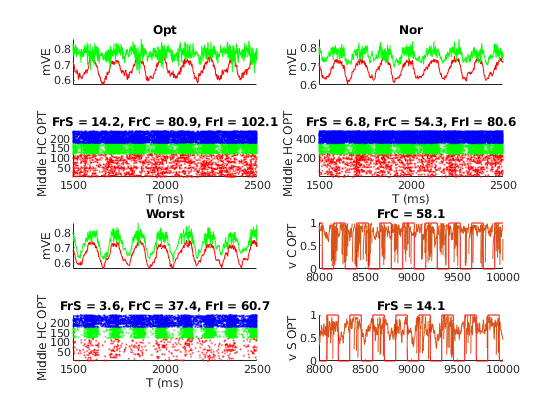

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1.25*n_S_HC & NnS.X<=1.75*n_S_HC;
MidRowS = NnS.Y>=1.25*n_S_HC & NnS.Y<=1.75*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1.25*n_C_HC & NnC.X<=1.75*n_C_HC;
MidRowC = NnC.Y>=1.25*n_C_HC & NnC.Y<=1.75*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [1500 2500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);